This is the first sheet demonstrating the use of our tools. Our tools are really 

1) mechanicasAsDAE -- solves a mechanics problem in a purely numerical manner, by treating it as a DAE. 

2) analyzeSystem -- Takes a system of DEs and constraints, and attempts to reduce it to a) a system of pure ODEs, and b) a list of "post-processing" equations that can be solved if the equations in a) are solved. 

3) timeStepODE -- can take the system of pure ODEs from analyzeSystem and then use a timestepper to solve. 

clear all

%In this cell we define the DEs and algebraic constraints that define our
%problem.  Define the uknown time-varying functions with x(t), y(t), etc.
%NOT plain variables like x, y. 
syms x(t) y(t) theta(t) Fx(t) Fy(t) t m g L
F=[Fx;Fy];
rG=[x;y];
m=1;
L=2;
g=9.81;

%F=ma
eq1=m*diff(rG,t,2)==(F-m*g*[0;1]);
MFG=cross(-[rG;0],[F;0]);
MFG=MFG("t");

%IG theta''=M
eq2=1/12*m*L^2*diff(theta,t,2) ==MFG(3);

%Keep the thing in place. 
eq3=rG==L/2*[sin(theta);-cos(theta)];

%DEs are *really* any equation that doesn't need to be differentiated any
%more.  So the equations of motion COLM and COAM equations go here. ALSO,
%constituative relations like F1=-F2 go here, because those doen't need any
%differentiation. 
DEs=[eq1;eq2];

%position constraints are any constraints that should be differentiated
%twice.  These would generally just include position function.  
posnConstraints=eq3;

%Velocity constraints are any constraints that should be differentiated
%once.  Those would generally only include velocity functions. In this
%exampel there are none, which we indicate with an empty vector. 
velConstraints=[];


The unknown functions (just the base functions, not derivatives) are: Fx(t),Fy(t),theta(t),x(t),y(t)
Initial Conditions:
Y0/YP0:
Fx: -3.574987 Fxt:0.000000
Fy: 8.996470 Fyt:0.000000
theta: 0.500000 thetat:1.000000
x: 0.479426 xt:0.877583
y: -0.877583 yt:0.479426
Dthetat: 1.000000 Dthetatt:-3.527373
Dxt: 0.877583 Dxtt:-3.574987
Dyt: 0.479426 Dytt:-0.813530


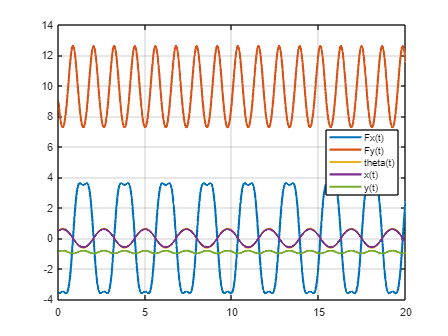

%Once we have the system of equations defined, we can solve it using purely
%numerical techniques.  Usage is avialbe via help mechanicasAsDAE or in the code of mechanicsAsDAE.  Here are some examples.  

%Solve on time interval [0,20]. 
soln=mechanicsAsDAE(DEs,posnConstraints,velConstraints,[0,20],[theta==0.5,diff(theta)==1]);


%The initial conditions need not refer to the same variable. This leads to
%multiple feasible initial conditions. No hint is provided, so the first
%initial condition is selected. 
%soln=mechanicsAsDAE([eq1;eq2],[eq3],[],[0,20],{x==0.5,diff(theta)==1});

%Same as above, but choose the initial condition that has y near one. 
%soln=mechanicsAsDAE([eq1;eq2],[eq3],[],[0,20],{x==0.5,diff(theta)==1},{y==1});

%Initial values can be given in a few different formats. Formats can be
%mixed-and-matched.
%soln=mechanicsAsDAE([eq1;eq2],[eq3],[],[0,20],{x(t)==0.5,diff(theta(t))==1},{y==1});
%soln=mechanicsAsDAE([eq1;eq2],[eq3],[],[0,20],{"x==0.5",diff(theta(t))==1},{y==1});
%soln=mechanicsAsDAE([eq1;eq2],[eq3],[],[0,20],{"x==0.5","Dthetat==1"},{y==1});

%Plotting is kind of annoying.  Turn it off. 
%soln=mechanicsAsDAE([eq1;eq2],[eq3],[],[0,20],{"x==0.5","Dthetat==1"},{y==1},0);
%Maybe the diagnostics bug you. Turn them off. 
%soln=mechanicsAsDAE([eq1;eq2],[eq3],[],[0,20],{"x==0.5","Dthetat==1"},{y==1},0,0);

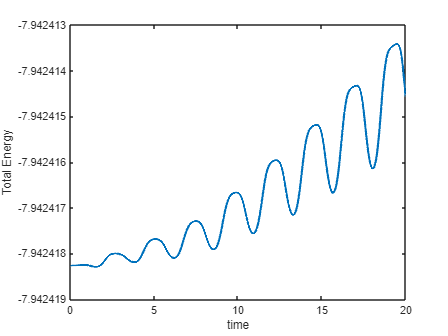

%The numerical solution has one field for each unknown.  Here we calculate
%the total energy of the system over time to see if it is holding steady.
%Not bad. 
KineticEnergy=1/2*m*(soln.Dxt.^2+soln.Dyt.^2) + 1/2*1/12*m*L^2*soln.Dthetat.^2;
PotentialEnergy=m*soln.y*g;
plot(soln.t,KineticEnergy+PotentialEnergy,'LineWidth',2)
xlabel('time'); ylabel('Total Energy')

%Now approach the same problem analytically.  Try to make the state
%variables theta and diff(theta,t). Find a closed form system of DEs in
%theta and diff(theta) that describe the system, and then a list of
%"post-processin" equations that tell you how to calculate all other
%quantities of interest once you have the state functions. 

%See help in the code of analyzeSystem. 

%Find the governing ODEs for a pendulum, and a formula for all other
%quantities of interest.  Express in terms of theta and diff(theta). 
[governingDEs,PP] = analyzeSystem(DEs,posnConstraints,velConstraints,[theta,diff(theta)])

The unknown functions are:
Fx(force)
Fy(force)
theta
x
y

Expected Number of State Variables:2


$$governingDEs = \frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=-\frac{2943\,\sin\left(\theta \left(t\right)\right)}{400}$$

$$PP = \begin{array}{l} \left(\begin{array}{c} \frac{\partial }{\partial t}x\left(t\right)=\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)=\sigma_{2}\\ \frac{\partial }{\partial t}y\left(t\right)=\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)=\sigma_{3}+\sigma_{1}-\frac{2943}{400}\\ \mathrm{Fx}\left(t\right)=\sigma_{2}\\ \mathrm{Fy}\left(t\right)=\sigma_{3}+\sigma_{1}+\frac{981}{400}\\ x\left(t\right)=\sin\left(\theta \left(t\right)\right)\\ y\left(t\right)=-\cos\left(\theta \left(t\right)\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{2943\,{\cos\left(\theta \left(t\right)\right)}^{2}}{400}\\ \sigma_{2}=-\sin\left(\theta \left(t\right)\right)\,\sigma_{4}-\frac{2943\,\sin\left(2\,\theta \left(t\right)\right)}{800}\\ \sigma_{3}=\cos\left(\theta \left(t\right)\right)\,\sigma_{4}\\ \sigma_{4}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2} \end{array}$$


%Turn off diagnostics. 
%[governingDEs,PP] = analyzeSystem(DEs,posnConstraints,velConstraints,[theta,diff(theta)],[],0)


%Same, but express in terms of x and diff(theta).  Note that you will get
%warned that there are multiple branches for x.  
%[governingDEs,PP] = analyzeSystem(DEs,posnConstraints,velConstraints,[x,diff(theta)])



%Once you have the pure ODE system, you can try to solve it using a
%standard tool.  For example, dsolve. 

%In general, dsolve probably won't work. But it is an option. 

[governingDEs] = analyzeSystem(DEs,posnConstraints,velConstraints,[theta,diff(theta)])

The unknown functions are:
Fx(force)
Fy(force)
theta
x
y

Expected Number of State Variables:2


$$governingDEs = \frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=-\frac{2943\,\sin\left(\theta \left(t\right)\right)}{400}$$

soln=dsolve(governingDEs)

$$soln = \left(\begin{array}{c} 0\\ 2\,\mathrm{am}\left(\frac{\sqrt{2}\,\left(C_{2}-t\right)\,\sqrt{C_{1}-2943}\,\mathrm{i}}{40}|-\frac{5886}{C_{1}-2943}\right)\\ -2\,\mathrm{am}\left(\frac{\sqrt{2}\,\left(C_{2}-t\right)\,\sqrt{C_{1}-2943}\,\mathrm{i}}{40}|-\frac{5886}{C_{1}-2943}\right) \end{array}\right)$$


%Now that you have a system of pure ODEs characterizing the system, you can
%solve it using any time-stepper.  timeStepODESystem is desiged to take the
%output of analyzeSystem and plug it in to ode23s. 

%See help in code of timeStepODESystem. 

%Get a governing DE in terms of theta, then timestep. 
[governingDEs,PP] = analyzeSystem(DEs,posnConstraints,velConstraints,[theta,diff(theta)])

The unknown functions are:
Fx(force)
Fy(force)
theta
x
y

Expected Number of State Variables:2


$$governingDEs = \frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=-\frac{2943\,\sin\left(\theta \left(t\right)\right)}{400}$$

$$PP = \begin{array}{l} \left(\begin{array}{c} \frac{\partial }{\partial t}x\left(t\right)=\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)=\sigma_{2}\\ \frac{\partial }{\partial t}y\left(t\right)=\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)=\sigma_{3}+\sigma_{1}-\frac{2943}{400}\\ \mathrm{Fx}\left(t\right)=\sigma_{2}\\ \mathrm{Fy}\left(t\right)=\sigma_{3}+\sigma_{1}+\frac{981}{400}\\ x\left(t\right)=\sin\left(\theta \left(t\right)\right)\\ y\left(t\right)=-\cos\left(\theta \left(t\right)\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{2943\,{\cos\left(\theta \left(t\right)\right)}^{2}}{400}\\ \sigma_{2}=-\sin\left(\theta \left(t\right)\right)\,\sigma_{4}-\frac{2943\,\sin\left(2\,\theta \left(t\right)\right)}{800}\\ \sigma_{3}=\cos\left(\theta \left(t\right)\right)\,\sigma_{4}\\ \sigma_{4}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2} \end{array}$$

The unknown functions (just the base functions, not derivatives) are: theta(t)


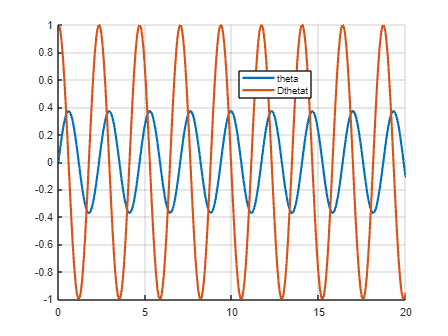

soln=timeStepODESystem(governingDEs,[0,20],{theta==0,diff(theta)==1},PP);



%Get a system in terms of theta, then time step, but don't plot your
%results and don't print diagnostics. 
%[governingDEs,PP] = analyzeSystem(DEs,posnConstraints,velConstraints,[theta,diff(theta)],[],0);
%soln=timeStepODESystem(governingDEs,[0,20],{theta==0,diff(theta)==1},PP,0,0);

%Get a system in terms of x and diff(theta).  This is dumb, but can be
%done. Note that the selected branches are only real as long as x<1.  As
%soon as that fails, things fall apart. 
%[governingDEs,PP] = analyzeSystem(DEs,posnConstraints,velConstraints,[x,diff(theta)])
%soln=timeStepODESystem(governingDEs,{x==0.5,[0,20],diff(theta)==0});



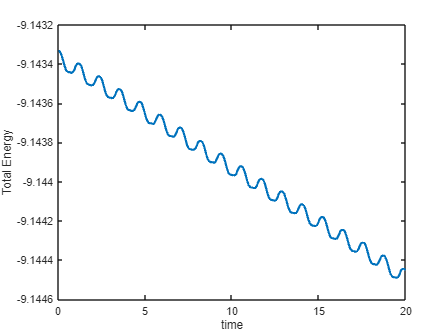



%Solution has a field for each unknown function now.  Do as you will with
%them. 

[governingDEs,PP] = analyzeSystem(DEs,posnConstraints,velConstraints,[theta,diff(theta)],[],0);
soln=timeStepODESystem(governingDEs,[0,20],{theta==0,diff(theta)==1},PP,0,0);

KineticEnergy=1/2*m*(soln.Dxt.^2+soln.Dyt.^2)+1/2*1/12*m*L^2*soln.Dthetat.^2;
PotentialEnergy=m*soln.y*g;
plot(soln.t,KineticEnergy+PotentialEnergy,'LineWidth',2)
xlabel('time'); ylabel('Total Energy')

%Sometimes is is possible to get a nice general system of ODE governing the
%system in terms of paramters.  Just leave parameters as undefined,
%*non-time-varying* symbolic variables.

clear m g L
syms m g L

eq1=m*diff(rG,t,2)==(F-m*g*[0;1]);
MFG=cross(-[rG(t);0],[F(t);0]);
eq2=1/12*m*L^2*diff(theta,t,2) ==MFG(3);
eq3=rG==L/2*[sin(theta);-cos(theta)];



[governingDEs,PP] = analyzeSystem([eq1;eq2],eq3,velConstraints,[theta,diff(theta)]);

The unknown functions are:
Fx(force)
Fy(force)
theta
x
y

Expected Number of State Variables:2


governingDEs

$$governingDEs = \frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=-\frac{3\,g\,\sin\left(\theta \left(t\right)\right)}{2\,L}$$

%This can work for non-autonomous systems. Getting a nice system for
%non-homogeneous ODE can work too. 
clear m g L 
syms m g L
eq1=m*diff(rG,t,2)==(F-m*g*[0;1]);
MFG=cross(-[rG(t);0],[F(t);0]);
eq2=1/12*m*L^2*diff(theta,t,2) ==MFG(3)+sin(t);  %<-- non-homogeneity added here. 
eq3=rG==L/2*[sin(theta);-cos(theta)];
[governingDEs,PP] = analyzeSystem([eq1;eq2],eq3,velConstraints,[theta,diff(theta)]);

The unknown functions are:
Fx(force)
Fy(force)
theta
x
y

Expected Number of State Variables:2


governingDEs

$$governingDEs = \frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=\frac{6\,\sin\left(t\right)-3\,L\,g\,m\,\sin\left(\theta \left(t\right)\right)}{2\,L^{2}\,m}$$


%You can also get general equations for non-autonomous equations where the non-homogeneous term is unspecified.  
%This will work for generic non-autonomous terms, but you need to declare
%that the term is a parameter. If you don't the solver may decide just to
%set your forcing term to 0. 

%This can work for non-autonomous systems. Getting a nice system for
%non-homogeneous ODE can work too. 
clear m g L 
syms m g L
syms forcing(t)
eq1=m*diff(rG,t,2)==(F-m*g*[0;1]);
MFG=cross(-[rG(t);0],[F(t);0]);
eq2=1/12*m*L^2*diff(theta,t,2) ==MFG(3)+forcing(t);  %<-- non-homogeneity added here. 
eq3=rG==L/2*[sin(theta);-cos(theta)];
[governingDEs,PP] = analyzeSystem([eq1;eq2],eq3,velConstraints,[theta,diff(theta)],forcing)

The unknown functions are:
Fx(force)
Fy(force)
theta
x
y

Expected Number of State Variables:2


$$governingDEs = \frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=\frac{6\,\mathrm{forcing}\left(t\right)-3\,L\,g\,m\,\sin\left(\theta \left(t\right)\right)}{2\,L^{2}\,m}$$

$$PP = \begin{array}{l} \left(\begin{array}{c} \frac{\partial }{\partial t}x\left(t\right)=\frac{L\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)}{2}\\ \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)=-\frac{\sigma_{3}}{4\,L\,m}\\ \frac{\partial }{\partial t}y\left(t\right)=\frac{L\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)}{2}\\ \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)=\frac{\sigma_{4}+\sigma_{1}-3\,g\,m\,L+\sigma_{2}}{4\,L\,m}\\ \mathrm{Fx}\left(t\right)=-\frac{\sigma_{3}}{4\,L}\\ \mathrm{Fy}\left(t\right)=\frac{\sigma_{4}+\sigma_{1}+g\,m\,L+\sigma_{2}}{4\,L}\\ x\left(t\right)=\frac{L\,\sin\left(\theta \left(t\right)\right)}{2}\\ y\left(t\right)=-\frac{L\,\cos\left(\theta \left(t\right)\right)}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=3\,g\,m\,L\,{\cos\left(\theta \left(t\right)\right)}^{2}\\ \sigma_{2}=6\,\sin\left(\theta \left(t\right)\right)\,\mathrm{forcing}\left(t\right)\\ \sigma_{3}=2\,m\,\sin\left(\theta \left(t\right)\right)\,L^{2}\,\sigma_{5}+3\,g\,m\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,L-6\,\cos\left(\theta \left(t\right)\right)\,\mathrm{forcing}\left(t\right)\\ \sigma_{4}=2\,m\,L^{2}\,\cos\left(\theta \left(t\right)\right)\,\sigma_{5}\\ \sigma_{5}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2} \end{array}$$


%You can have a non-homogeneous problem and time step it. 
m=2; g=9.81; L=1.5;
eq1=m*diff(rG,t,2)==(F-m*g*[0;1]);
MFG=cross(-[rG(t);0],[F(t);0]);
eq2=1/12*m*L^2*diff(theta,t,2) ==MFG(3)+sin(t);  %<-- non-homogeneity added here. 
eq3=rG==L/2*[sin(theta);-cos(theta)];
[governingDEs,PP] = analyzeSystem([eq1;eq2],eq3,velConstraints,[theta,diff(theta)]);

The unknown functions are:
Fx(force)
Fy(force)
theta
x
y

Expected Number of State Variables:2


governingDEs

$$governingDEs = \frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=\frac{2\,\sin\left(t\right)}{3}-\frac{981\,\sin\left(\theta \left(t\right)\right)}{100}$$

soln=timeStepODESystem(governingDEs,[0,20],[theta==0,diff(theta)==0],[],0);

The unknown functions (just the base functions, not derivatives) are: theta(t)


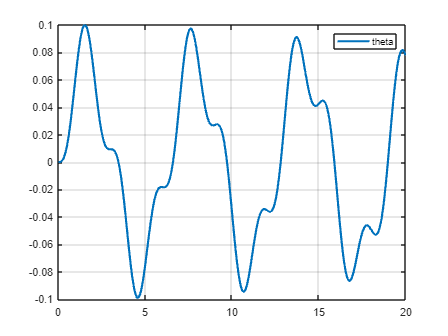

plot(soln.t,soln.theta,'LineWidth',2); legend("theta"); grid on;

%You can have a non-autonomous system and treat it as a DAE from the get
%go. 
%You can have a non-homogeneous problem and time step it. 
m=2; g=9.81; L=1.5;
eq1=m*diff(rG,t,2)==(F-m*g*[0;1]);
MFG=cross(-[rG(t);0],[F(t);0]);
eq2=1/12*m*L^2*diff(theta,t,2) ==MFG(3)+sin(t);  %<-- non-homogeneity added here. 
eq3=rG==L/2*[sin(theta);-cos(theta)];
soln=mechanicsAsDAE([eq1;eq2],eq3,[],[0,20],{theta==0,diff(theta)==0},[],0);

The unknown functions (just the base functions, not derivatives) are: Fx(t),Fy(t),theta(t),x(t),y(t)
Initial Conditions:
Y0/YP0:
Fx: 0.000000 Fxt:0.000000
Fy: 19.620000 Fyt:0.000000
theta: 0.000000 thetat:0.000000
x: 0.000000 xt:0.000000
y: -0.750000 yt:0.000000
Dthetat: 0.000000 Dthetatt:0.000000
Dxt: 0.000000 Dxtt:0.000000
Dyt: 0.000000 Dytt:0.000000


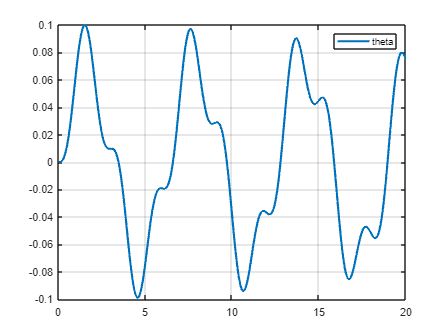

plot(soln.t,soln.theta,'LineWidth',2); legend("theta"); grid on;